# INF250 - CA5 - Deadline May 16th @ 23:59

### Upload your CA5_<Student Name>.mlx submission on Mitt, make sure it is the correct version and double-check (for example by downloading and running it again) to make sure you submitted the right file!

During the fifth round of programming assignments, we focus on a machine learning. To be a bit more specifically: LDA, Decision Trees, and Bayesian Networks.

## Linear Discriminant Analysis (LDA) - 25% of the points:

In the first part of the assignment, we focus on *multi-class linear discriminant analysis*, sometimes also referred to as *multiple discriminant analysis*. LDA corresponds to a *supervised *algorithm meaning that the underlying data is already divided into different classes/categories and we actively use this information. Therefore, we are this time working with the famous *Iris Data Set* (from Fisher, 1936) - UCI Machine Learning Repository ([https://archive.ics.uci.edu/ml/datasets/Iris](https://archive.ics.uci.edu/ml/datasets/Iris)).

Your first task is to import the data, either by downloading the data set from the above webpage or by simply using MATLABs corresponding sample data set.

**Hint: ***An overview of MATLABs sample data sets is available under *[https://se.mathworks.com/help/stats/sample-data-sets.html](https://se.mathworks.com/help/stats/sample-data-sets.html).

clc; clear; close all;

load fisheriris.mat
N = size(meas,1);


To understand the data better, your next task is to create a visualization consisting of four sub-plots. Each sub-plot should thereby be a histogram of one of the features provided in the data, i.e., the *sepal length*, the *sepal width*, the *petal length*, and the* petal width*. As always, make sure that each sub-plot has an x-axis and y-axis label, and a legend. In addition, play around with face color and face alpha to maximize the expressiveness of your information visualization. Think about how many bins you want to use, how many bins would be too little, how many bins would be too many?

**Hint: ***The MATLAB 'subplot' functionality might be useful to create visualizations consisting of several sub-plots.*

**Hint: ***The MATLAB 'histogram' functionality might be useful to create histograms. Additionally, make sure to check out the 'edges', 'FaceColor', and 'FaceAlpha' parameters.*

**Hint: ***The MATLAB 'hold on' and 'hold off' functionalities might be useful to create histograms of multiple categories (e.g., setosa, vericolor, and virginica) by using several function calls on the same plot.*

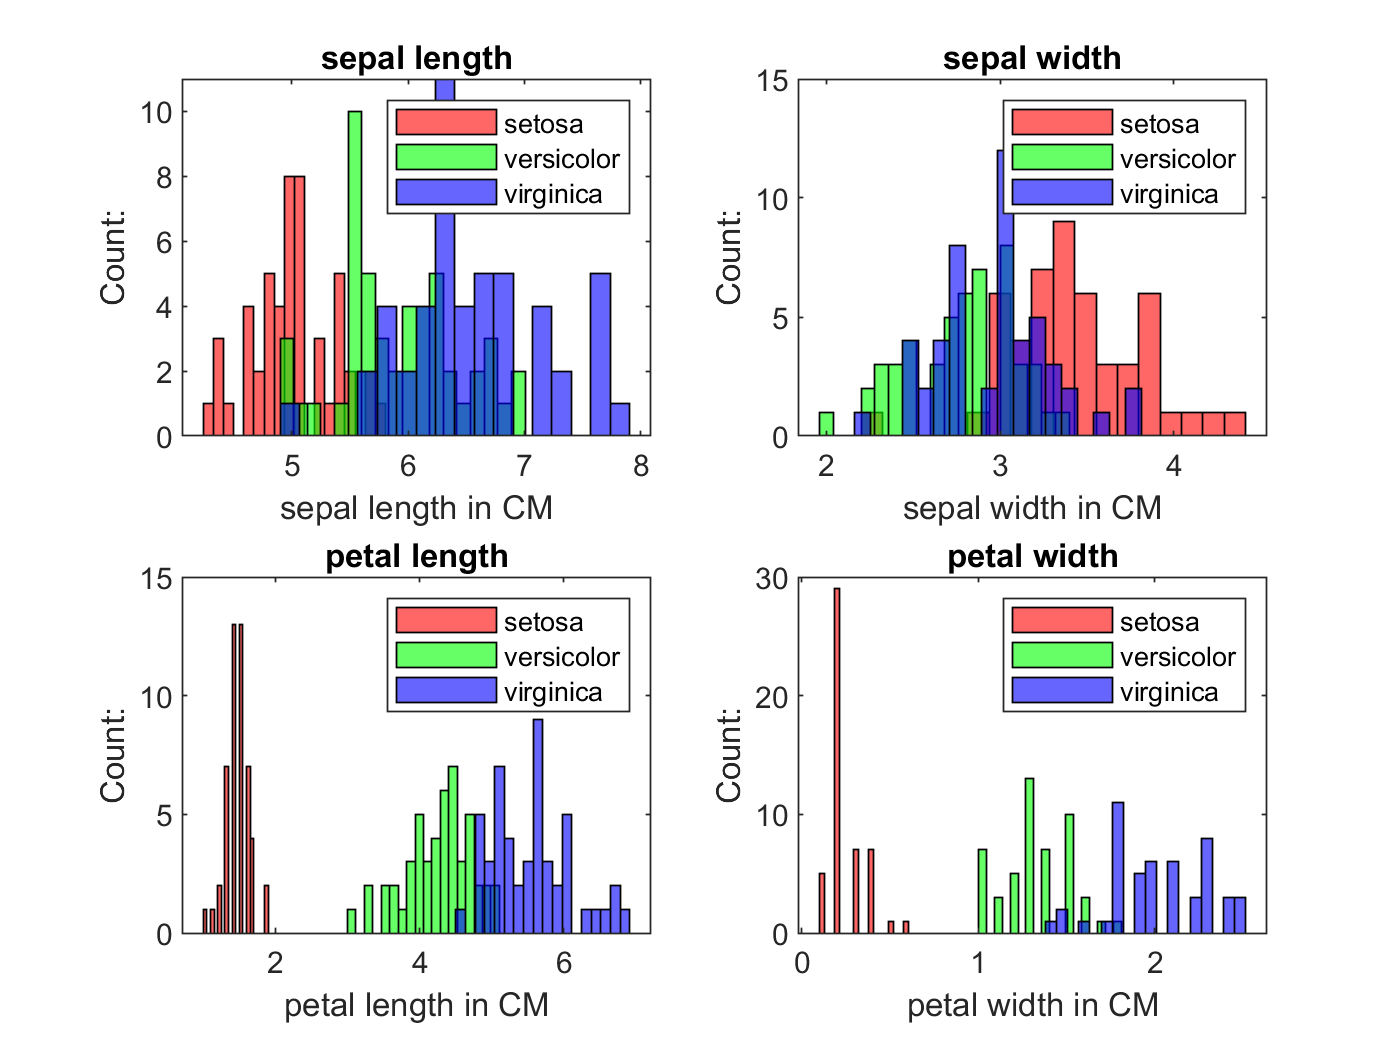

Too small (fixed) number of bins lead to plots like this. Where the different flower-histograms have different width, resulting in messy unreadable plots. 

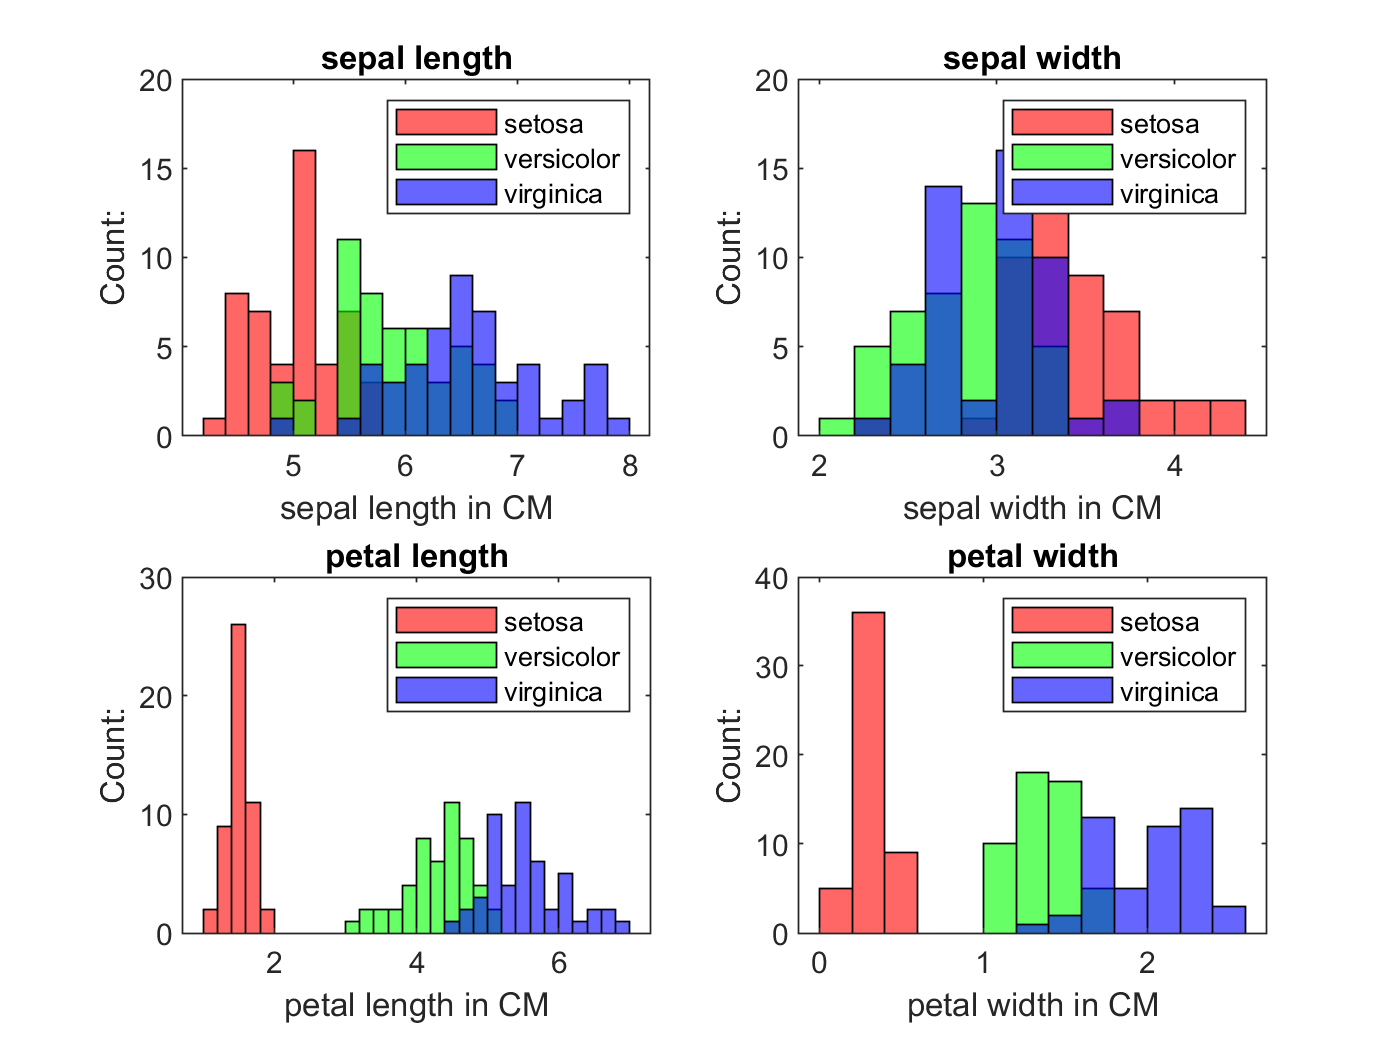

Whereas with fixed bin widths lead to plots like this. Much more readable, and gives a better picture of the data.

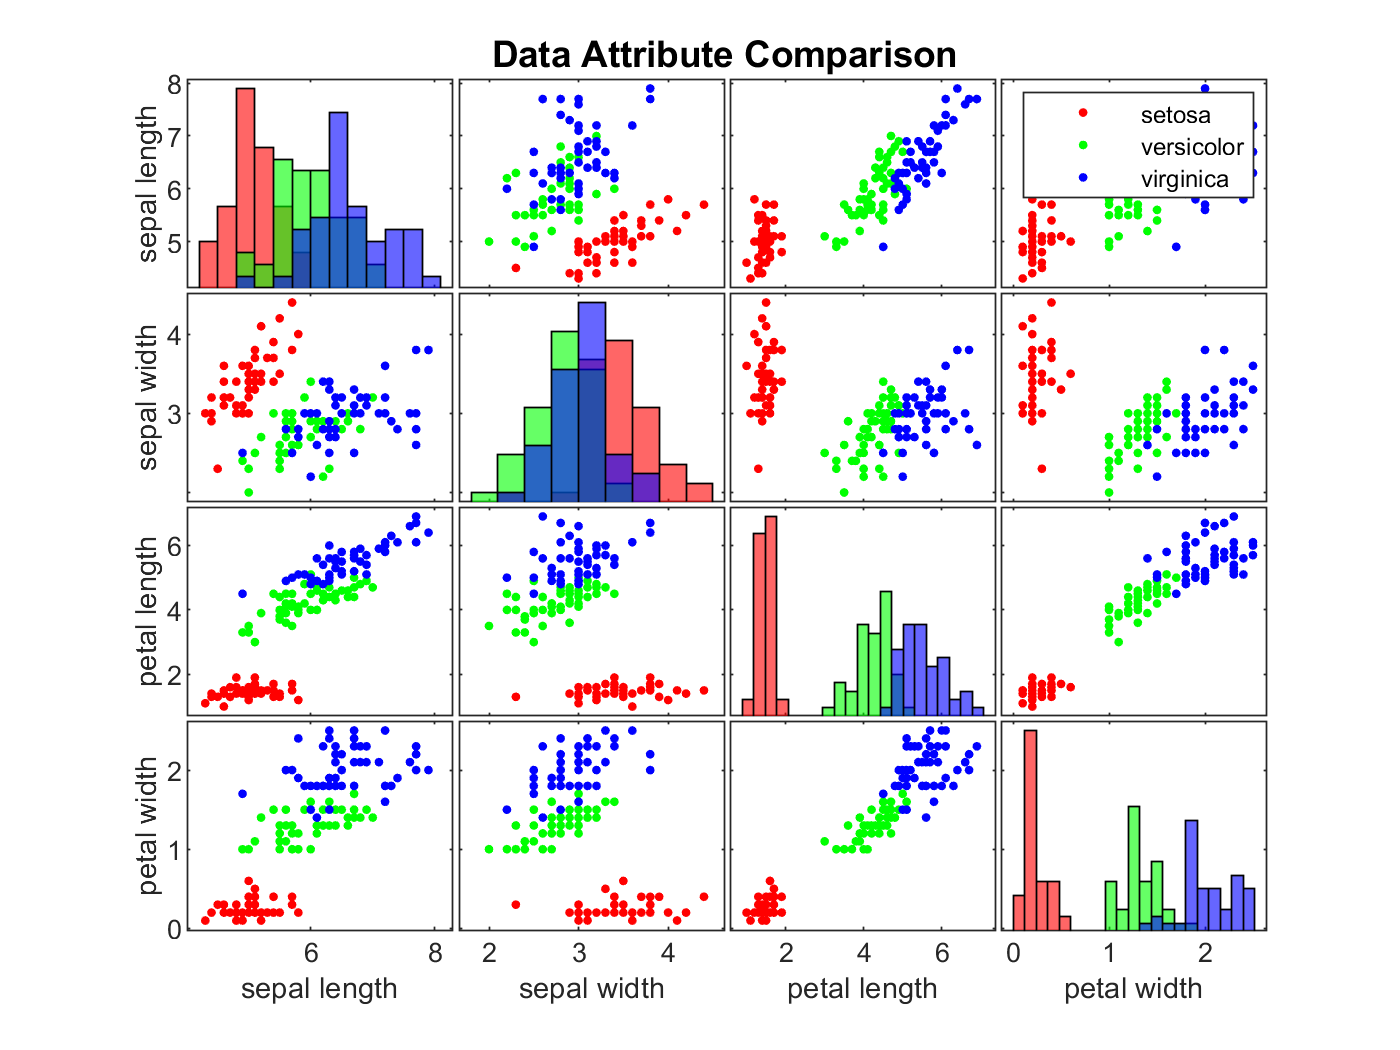

% I created a few different plots before landing on these two. I found this
% great function - gplotmatrix. Which essencially does exactly what we
% want. It compares all attributes with all the other attributes. In the
% gplotmatrix function all parameters are given directly to the function,
% and the function then creates the plot. This gives a little less control
% over how the final plot will look like. But it's still by far the most
% expressive plot. 

% In my testing I tried different scatterplots, matrixplots, histograms. I
% found histograms and scatterplots to be equally good. Individual
% datapoints are more expressive in scatterplots than in histograms, and
% you get a sense of the density. Histograms are very good at showing the
% groupings, espesially when the bars have different colors. This is also a
% reason for why i chose gplotmatrix.

vns = {'sepal length' 'sepal width' 'petal length' 'petal width'};
gplotmatrix(meas,[], species, "rgb",[],[],[],'grpbars', vns)
title("Data Attribute Comparison")



% I also chose to include this histogram. Primarily to show how the
% groupings are quite visible. Espesially when looking at petal length and
% width. As for colors and opacity, i chose the most common colors red,
% green, and blue as they all contrast eachother very nicely. (Given that
% the person looking on them is not colorblind). And as for opacity, the
% default was sufficient. There is not alot of overlap between the bars, so
% the opacity should not be very high.

% I also decided to go with a binwidth of 0.2, as a fixed bin-width worked
% the best for me.

c = ["r", "g", "b"];
specieslabels = [species(1) species(51) species(150)];
measlabels = ["sepal length" "sepal width" "petal length" "petal width"];
figure(2);
for i = 1:4
    subplot(2,2,i)
    
    for k = 1:1:3
        histogram( meas((k-1) * 50 +1: k*50, i), "BinWidth", 0.20, "FaceColor",c(k))
        hold on
    end
    legend(specieslabels)
    title(measlabels(i))
    xlabel(measlabels(i) + " in CM")
    ylabel("Count:")
    hold off

end

Generally, LDA assumes normally distributed data, therefore, your task is to next check whether the individual categories are normally distributed. Note, however, that discriminant analysis is relatively robust to "slight" violations of this assumption, according to Lachenbruch, P. A. (1975) - *Discriminant analysis*. 

Use *Jarque-Bera test* to test if the data comes from a normal distribution with an unknown mean and variance at a 5% significance level. What does the test reveal about the categories within data?

**Hint: ***The MATLAB 'jbtest' functionality might be useful to perform a Jarque-Bera test.*




% I created a double (nested) for-loop to check all possible "category
% permutations". By this I mean each flowertype is tested seperately from the
% other flowers, as well as each flowers attributes is tested. 

% In my testing, all but one hypothesistests are accepted. The failed test
% checks the petal-width for the plant Setosa. As seen in the lower right
% subplot, these datapoints are very clustured and separate from the other
% data. The fact the data fails the test does not mean that the data is not
% from the normal distribution. It's rather an indiation that some extreme
% values have shown up, and skews our distribution more than expected. 


for i = 1:4    
    for k = 1:1:3
        data = meas((k-1)*50 + 1: k*50, i);
        jbtest(data)
    end
end

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0

ans = 1

ans = 0

ans = 0

After exploring the histograms, you chose to use *petal length* and *petal width* as basis for a linear classifier. Create a new figure containing only a scatter plot using *petal length* as x-axis and *petal width* as y-axis. Use the same colors as you already used in your histograms to color different classes and use varying marker symbols. Then, plot two lines - resulting from MATLABs linear discriminant analysis classifier - that can be used to separate all three classes accordingly. What do you observe? Do all data points get classified correctly? If not, how many are wrongly classified? 

**Hint: ***The MATLAB 'gscatter' functionality might be useful to create a scatter plot.*

**Hint: ***The MATLAB 'fitcdiscr' functionality might be useful to create a linear discriminant analysis classifier.*

**Hint: ***The MATLAB 'fimplicit' functionality might be useful to plot an implicit function.*

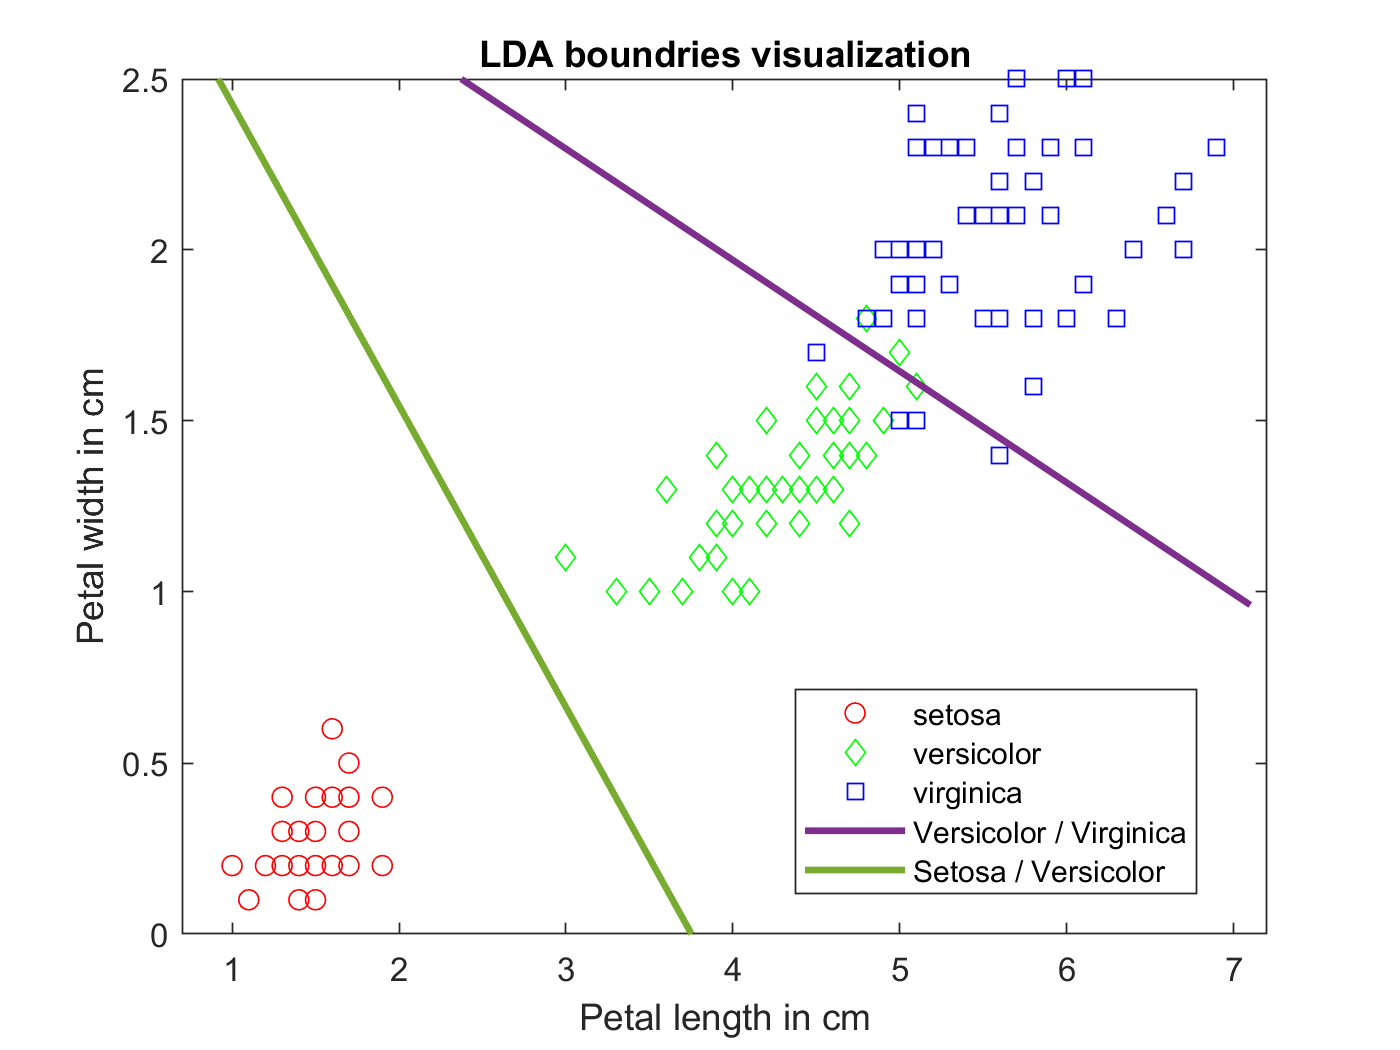


Mdl = fitcdiscr(meas(:,3:4), species);
const1 = Mdl.Coeffs(2,3).Const;
linear1 = Mdl.Coeffs(2,3).Linear;
func1 = @(x1,x2) const1 + linear1(1)*x1 + linear1(2)*x2;


const2 = Mdl.Coeffs(1,2).Const;
linear2 = Mdl.Coeffs(1,2).Linear;
func2 = @(x1,x2) const2 + linear2(1)*x1 + linear2(2)*x2;

figure(4);
gscatter(meas(:,3), meas(:,4), species, "rgb", "ods")
hold on
h2 = fimplicit(func1,[.9 7.1 0 2.5]);
h2.DisplayName = "Versicolor / Virginica";
h2.LineWidth = 2;

h3 = fimplicit(func2,[.9 7.1 0 2.5]);
h3.DisplayName = "Setosa / Versicolor";
h3.LineWidth = 2;

xlabel("Petal length in cm")
ylabel("Petal width in cm")
title("LDA boundries visualization")
hold off

## LDA Summary - mandatory to receive points:

Use the box below to tell us what you learned when implementing LDA. What is *petal* or *sepal* width/length? How many bins did you use when creating the individual histograms (how many bins would be too much/ too little)? By looking at all four histograms, can you tell which features are likely better suited to separate between the three flower classes, i.e., sepal VS petal properties or length VS width properties? What did Jarque-Bera test reveal about the data, are all categories normal distributed? What other tests could you perform to find out whether a variable is normal distributed? What did you observe when performing your linear discriminant analysis classification? Were sample points misclassified? If so, which classes could be nicely separated and which not?

%{ --> add your answer as comment here!

% Petals are quite simple, its the parts of the flower that make it a
% flower so to speak. Small usually colorful and soft leaves that attract
% insects. The width and height of the petals are simply the width and
% height of an individual such leaf. Sepals are the (usually) green leaves
% that are around the flower petals before the flower blooms. They are
% usually more robust, green, and are more "leafy" than petals. The sepal
% width and length are again simply the width and length of such a leaf.

% I found a fixed bin-width of 0.2 to be the most expressive. This allowed
% the plots to express the data differently based on how spread out the
% data is. I would be difficult to find a single bin_number to fit all the
% separate dataset equally well. Atleast with a fixed binsize, the meaning
% of each bin is apparant. If the bin_number is fixed, then the meaning of
% the bins is changed from plot to plot. As i mentioned its difficult to
% find a number to fit them all. But for the sake of the exercise, too few
% bins: ~8, too many: > 20.

% It is quite clear that both petal-properties are much better at
% separating the flower-types. In both cases the setosa flower is
% completely disjunct from the other two. And the distribution of the two
% others are at a slight offset, so it should be possible to separate them
% efficiently. (Although some overlap between versicolor and virginica).

% FROM ABOVE:
% In my testing, all but one hypothesistests are accepted. The failed test
% checks the petal-width for the plant Setosa. As seen in the lower right
% subplot, these datapoints are very clustured and separate from the other
% data. The fact the data fails the test does not mean that the data is not
% from the normal distribution. It's rather an indiation that some extreme
% values have shown up, and skews our distribution more than expected. 
% OTHER TEST: We could check the data visually, check for outliers, use a
% Kolmogorov Smirnov test, Lilliefors test, or a Shapiro Wilk test.

% I observed that the data is almost entirely "splittable". However not
% completely. Which leads to some samples being mislabeled. This is due to
% there being some overlap between the two flowers, versicolor and
% virginica. 

% Setosa was very easy to separate and thus very easy to classify.


%}

## Decision Trees - 25% of the points:

In the second part of the assignment, we focus on decision trees, here also used for classification. We, therefore, continue working with the *Iris Data Set* (from Fisher, 1936) - UCI Machine Learning Repository ([https://archive.ics.uci.edu/ml/datasets/Iris](https://archive.ics.uci.edu/ml/datasets/Iris)). If you have not loaded the data, for example, because you skipped the LDA exercise, make sure you load it now, otherwise it is already in your workspace :)

**Hint: ***An overview of MATLABs sample data sets is available under *[https://se.mathworks.com/help/stats/sample-data-sets.html.](https://se.mathworks.com/help/stats/sample-data-sets.html.)

Then, create a binary decision tree and visualize the resulting tree as:

- text description, and

- graphic description.

**Hint: ***The MATLAB 'fitctree' functionality might be useful to fit a binary decision tree for multiclass classification*

**Hint: ***The MATLAB 'view' functionality and its parameters might be useful to visualize the decision tree as text or graph.*

t = fitctree(meas, species, 'PredictorNames',{'Sepal length', 'Sepal width', 'Petal length', 'Petal width'});
view(t);

Decision tree for classification
1  if Petal length<2.45 then node 2 elseif Petal length>=2.45 then node 3 else setosa
2  class = setosa
3  if Petal width<1.75 then node 4 elseif Petal width>=1.75 then node 5 else versicolor
4  if Petal length<4.95 then node 6 elseif Petal length>=4.95 then node 7 else versicolor
5  class = virginica
6  if Petal width<1.65 then node 8 elseif Petal width>=1.65 then node 9 else versicolor
7  class = virginica
8  class = versicolor
9  class = virginica



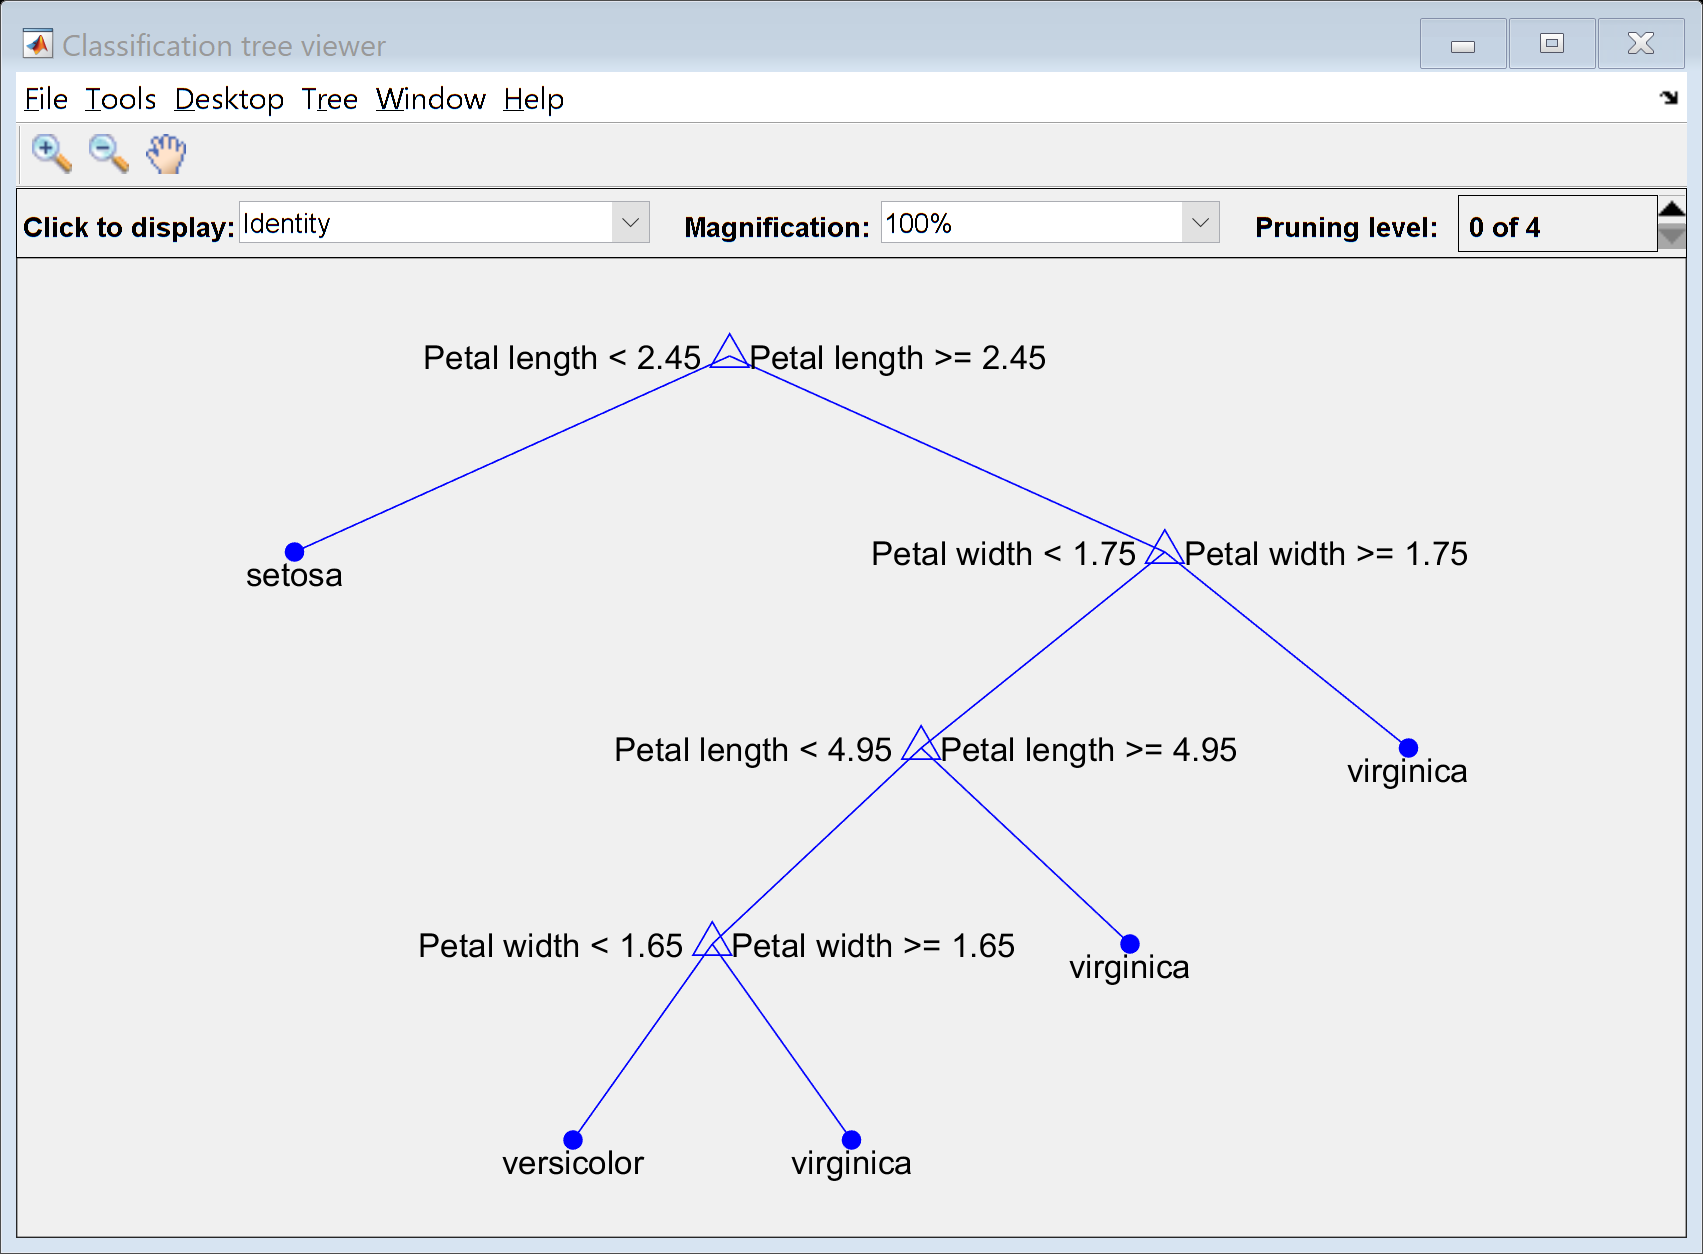

view(t,'Mode','graph');

There are different techniques of how to evaluate/predict the accuracy of a decision tree. We focus on one possibility namely *cross-validation*. Particularly, we focus on *k-fold* and *leave-one-out cross-validation* (*LOOCV*). Your task is to first calculate the predicted accuracy/classification loss for the previously generated decision tree using MATLABs *cross-validation* functionality for k=5.

**Hint: ***The MATLAB 'crossval' functionality might be useful for k-fold cross-validation. Check the necessary parameters for 5-fold cross-validation.*

**Hint: ***The MATLAB 'cvloss' functionality might alternatively be useful for cross-validation. Check the parameters for 5-fold cross validation.*

rng('default')
cval = crossval(t, 'KFold', 5);
L = kfoldLoss(cval);

% About 8 miscalculations (0.0533 / 150)
disp("K-fold loss " + L)

K-fold loss 0.06


Second, you will *manually* calculate LOOCV. Note that this time, you are not allowed to estimate the LOOCV using a MATLAB function (for example 'crossval', 'cvloss', and so on) but instead, you should loop over your data set, create a decision tree by leaving a single data item out and then, use exactly this data item as input for your prediction. Was the left-out item correctly classified?

LOOCV: [https://en.wikipedia.org/wiki/Cross-validation_(statistics)#Leave-one-out_cross-validation](https://en.wikipedia.org/wiki/Cross-validation_(statistics)#Leave-one-out_cross-validation)

meas_size = size(meas);
species_size = size(species);
loss = 0;

for i = 1:1:150
    temp = meas;
    temp(i,:) = [];
        
    temp_s = species;
    temp_s(i) = [];
    
    t = fitctree(temp, temp_s);
    
    % (If not strings t.predict(meas(i,:)) and species(i) are the same)
    if ~strcmp(cell2mat(t.predict(meas(i,:))), cell2mat(species(i)))
        loss = loss + 1;
    end

end
disp("LOOCV loss " + loss / 150)

LOOCV loss 0.046667



% As you can se the result is slightly better. Previously we had eight
% miscalculations, now only 7. It seems impossible for the desision tree to
% be able to include all cases. I would probably not bother with LOOCV in
% this case, as the results are in no way incredible.


## Decision Tree Summary - mandatory to receive points:

Use the box below to tell us what you learned when implementing the decision tree assignment. Is there a class that is especially easy to classify? Given the computational effort of leave-one out cross-validation, would you use it on rather large data sets (consisting of thousands or millions of entries) or smaller data sets? What does the 'k' in k-fold cross-validation stand for? What happens if k is equal to the size of the data set?

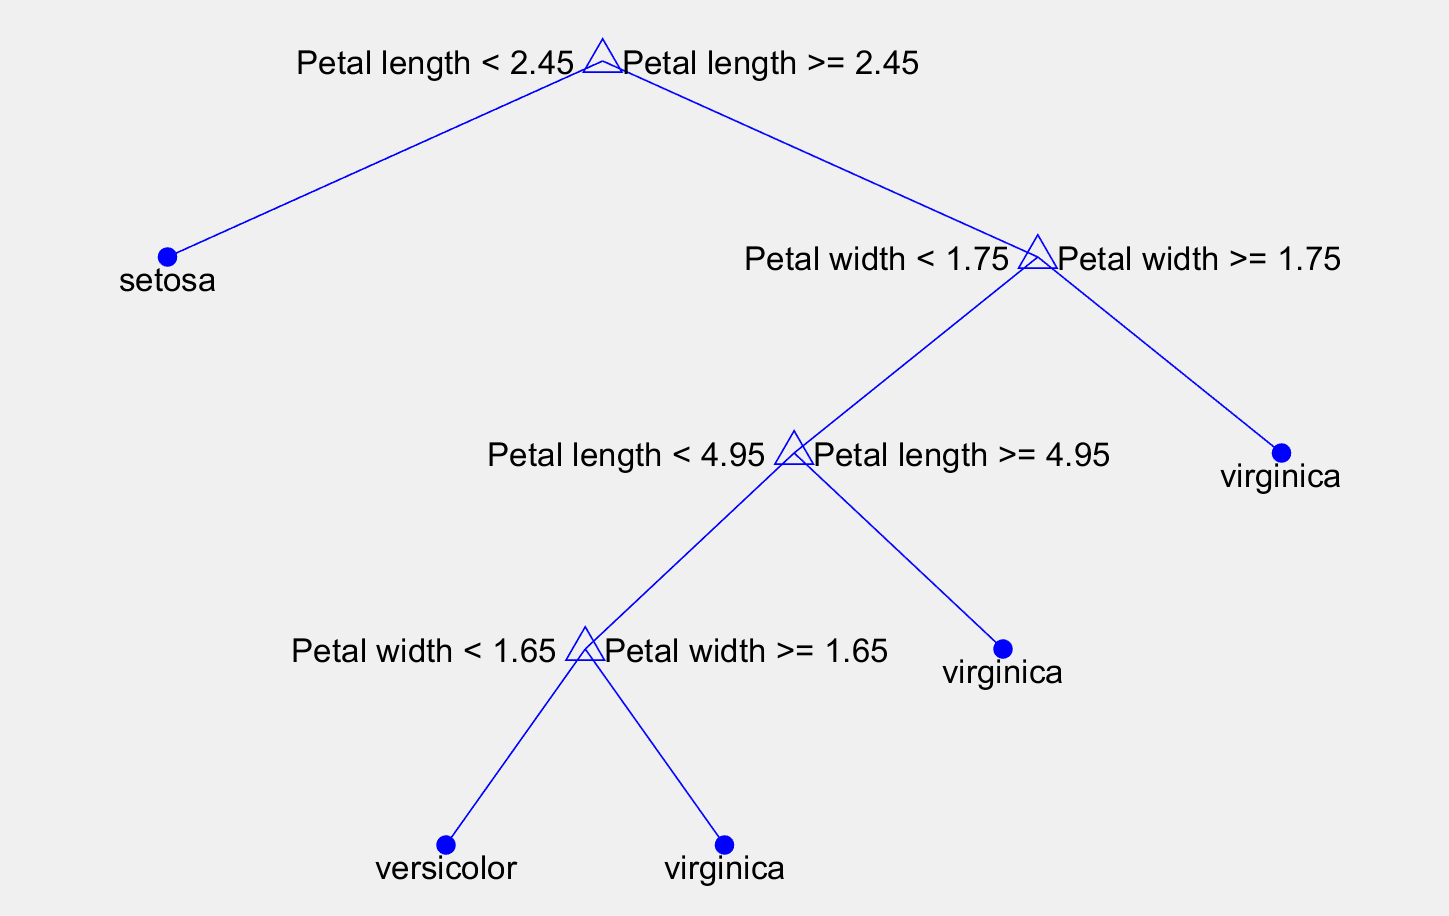

`Decision tree for classification`

`1  if Petal length<2.45 then node 2 elseif Petal length>=2.45 then node 3 else setosa`

`2  class = setosa`

`3  if Petal width<1.75 then node 4 elseif Petal width>=1.75 then node 5 else versicolor`

`4  if Petal length<4.95 then node 6 elseif Petal length>=4.95 then node 7 else versicolor`

`5  class = virginica`

`6  if Petal width<1.65 then node 8 elseif Petal width>=1.65 then node 9 else versicolor`

`7  class = virginica`

`8  class = versicolor`

`9  class = virginica`

%{ --> add your answer as comment here!
% The setosa flower is the easiest to classify. It is possible to classify
% it completely based on petal length being in a current range.

% LOOCV is only computationally suitable for small datasets.
% Training/fitting a model is very expensive, espesially when the models
% get more complex. Thus the computational cost quickly grows to much.

% The K in k-fold cross validation stands for how many sub-datasets we want
% to split the data into. Then train the model on k-1 of these sets, and
% validate on the last. So if k is equal to the size of the data, we end up
% with LOOCV. Where the model is fit to all datapoints, but one, and then
% tries to classify the last datapoint. 
%}

## Bayesian Networks - 50% of the points:

During the last part of this assignment, we focus on the *Bayes Net Toolbox for Matlab *provided by the University of Utah - School of Computing ([https://www.cs.utah.edu/~tch/notes/matlab/bnt/docs/bnt_pre_sf.html](https://www.cs.utah.edu/~tch/notes/matlab/bnt/docs/bnt_pre_sf.html)). Your first task is, therefore, to download and install the toolbox.

GitHub Repository: [https://github.com/bayesnet/bnt](https://github.com/bayesnet/bnt)

HowToInstall (Tested on MATLAB R2020a): [https://github.com/bayesnet/bnt/wiki/HowToInstall](https://github.com/bayesnet/bnt/wiki/HowToInstall)

**Hint: ***For your submission, you can assume that the Bayes Net Toolbox for Matlab is already installed on the machine that is used to correct your assignment. There is, therefore, no need to include any additional files of functions.*

To get familiar with the toolkit, your next task is to reimplement the Bayesian network used during lecture (INF250-VisIntro-L7a-ML1--print.pdf), also shown in the figure below:

                                                              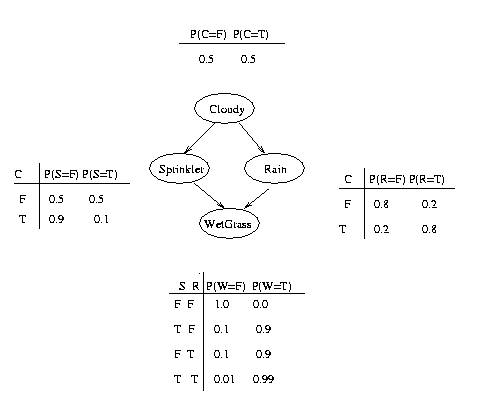

**Hint: ***Bayes Net Toolbox for Matlab provides a usage example of exactly this example network (*[https://www.cs.utah.edu/~tch/notes/matlab/bnt/docs/usage.html](https://www.cs.utah.edu/~tch/notes/matlab/bnt/docs/usage.html))

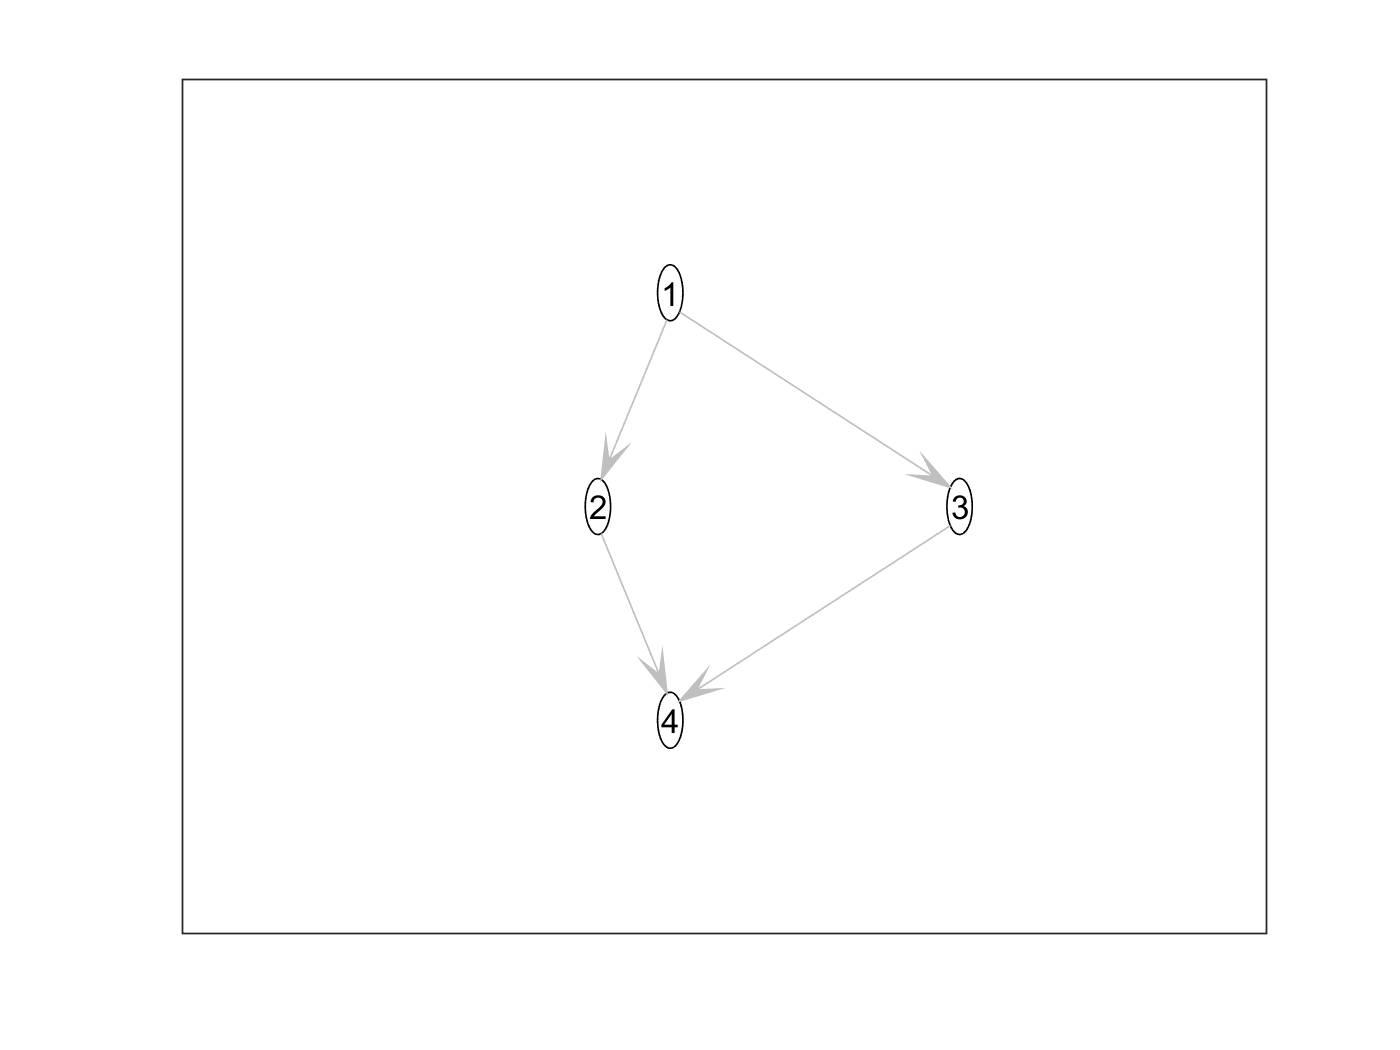

clc; clear; close all;

% Chose to go with the logical version

N = 4; 
dag = false(N,N);
C = 1; S = 2; R = 3; W = 4;
dag(C,[R S]) = true;
dag(R,W) = true;
dag(S,W) = true;

discrete_nodes = 1:N;
node_sizes = 2*ones(1,N); 

bnet = mk_bnet(dag, node_sizes, 'names', {'cloudy','S','R','W'}, 'discrete', 1:4);

bnet.CPD{C} = tabular_CPD(bnet, C, [0.5 0.5]);
bnet.CPD{R} = tabular_CPD(bnet, R, [0.8 0.2 0.2 0.8]);
bnet.CPD{S} = tabular_CPD(bnet, S, [0.5 0.9 0.5 0.1]);
bnet.CPD{W} = tabular_CPD(bnet, W, [1 0.1 0.1 0.01 0 0.9 0.9 0.99]);

engine = jtree_inf_engine(bnet);

draw_graph(bnet.dag);

To evaluate whether your implementation is correct, calculate:

- Probability that the sprinkler was on given that the grass is wet.

- Probability that the sprinkler was on given that the grass is wet, and it is raining.

**Hint: ***Again,* *Bayes Net Toolbox for Matlab provides both calculations as their usage examples (*[https://www.cs.utah.edu/~tch/notes/matlab/bnt/docs/usage.html](https://www.cs.utah.edu/~tch/notes/matlab/bnt/docs/usage.html))

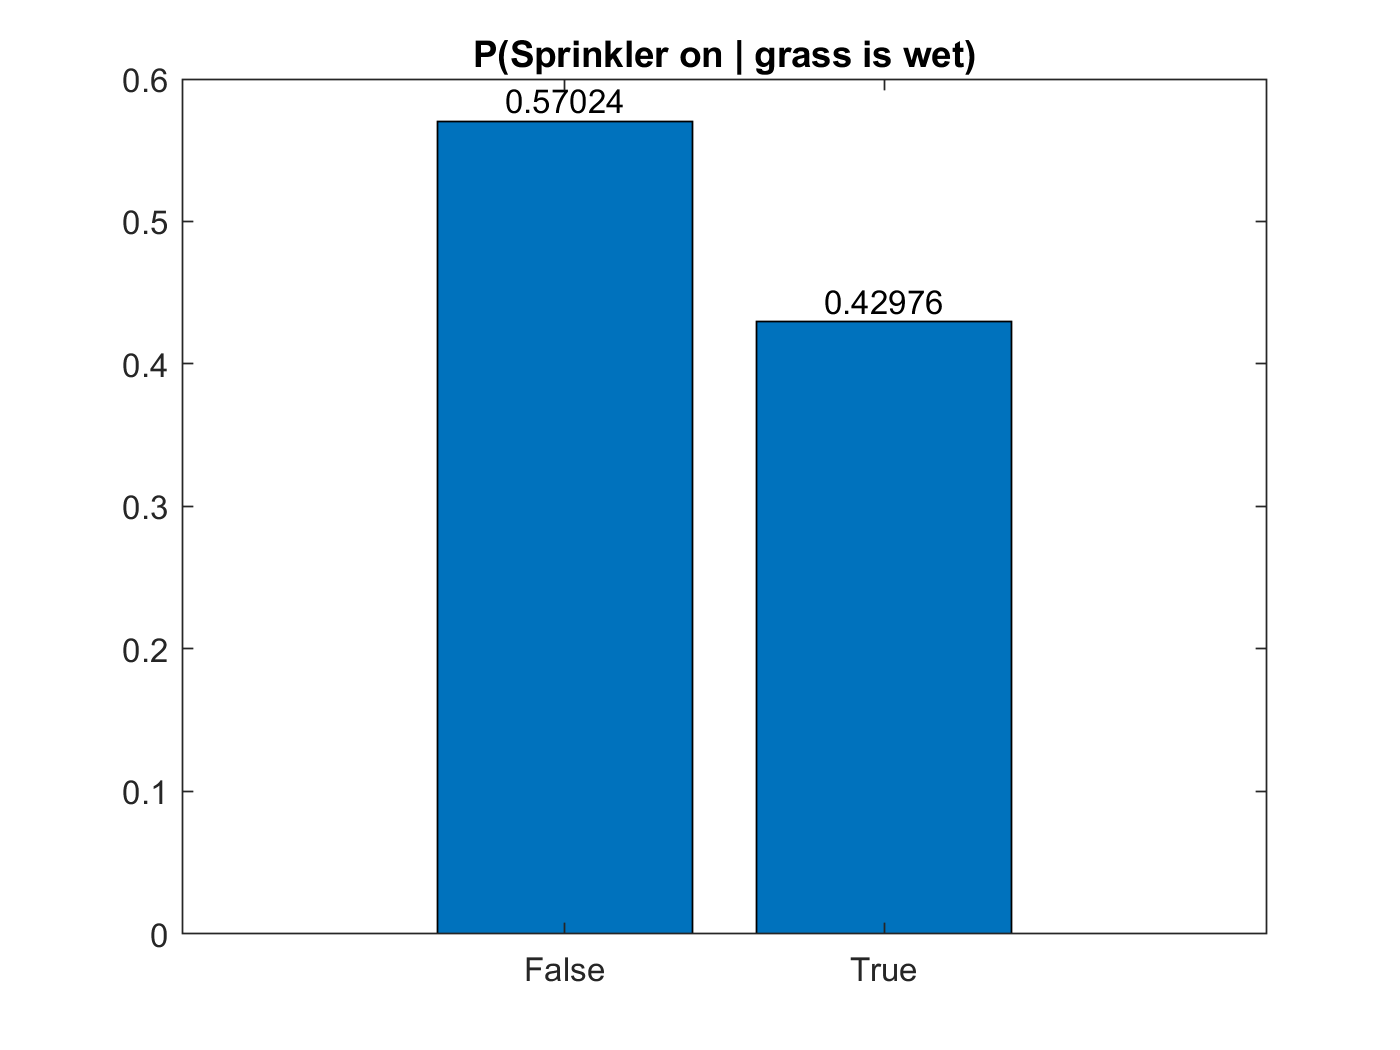

% 1.) Probability that the sprinkler was on given that the grass is wet.
evidence = cell(1,N);
evidence{W} = 2;
[engine, loglik] = enter_evidence(engine, evidence);
marg = marginal_nodes(engine, S);
bar(marg.T)
text(1:2,marg.T,num2str(marg.T),'vert','bottom','horiz','center'); 
title("P(Sprinkler on | grass is wet)")
set(gca,'xticklabel',{'False','True'})

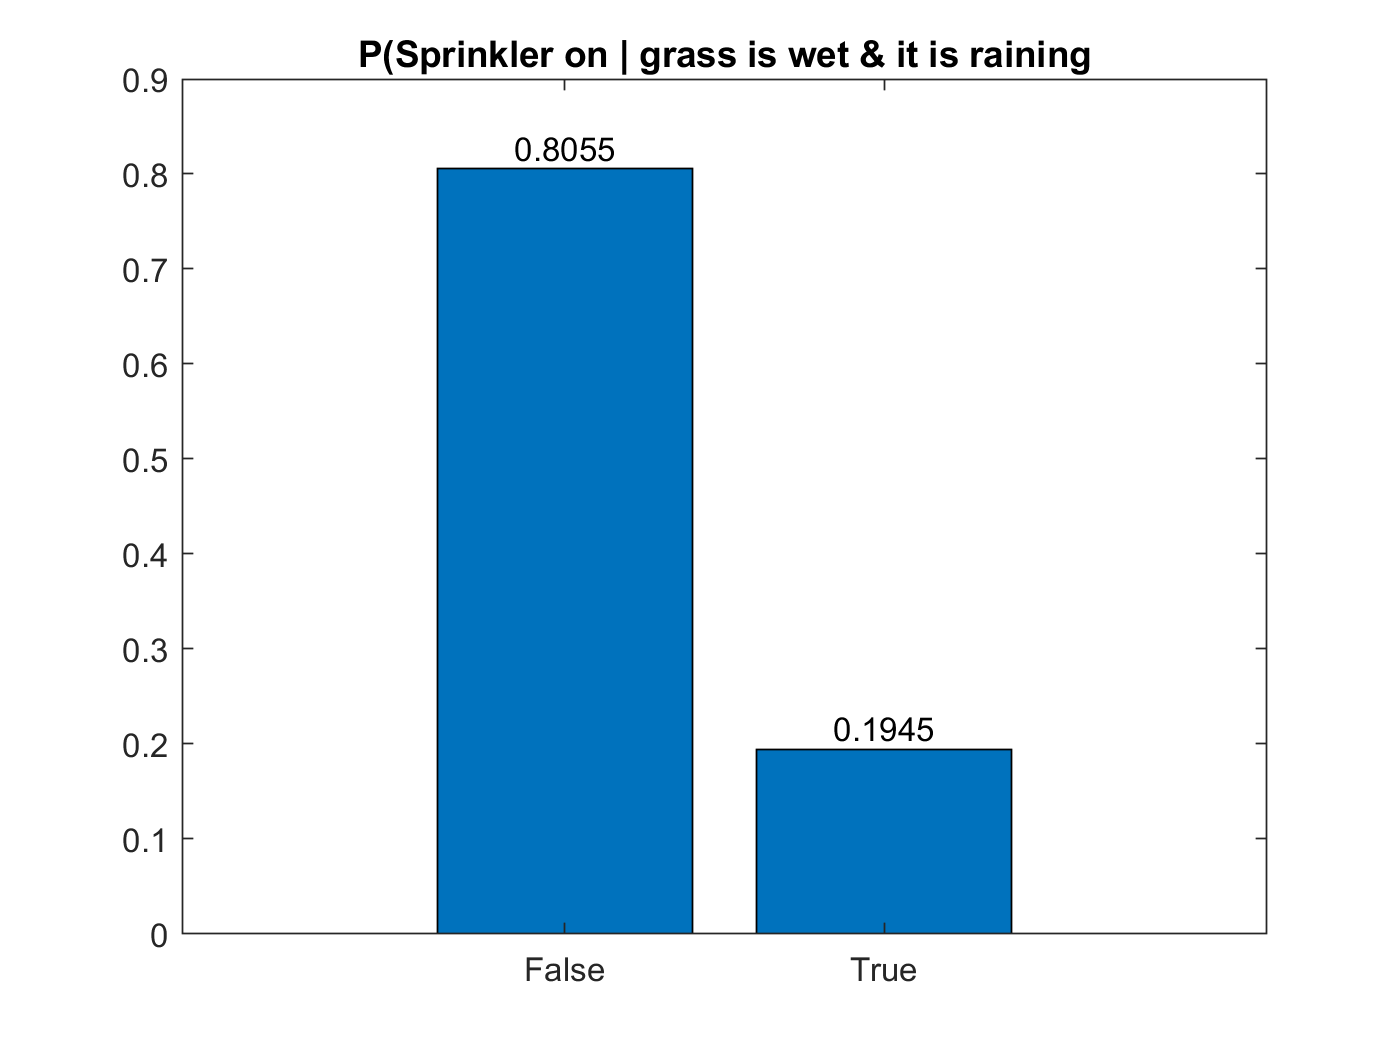


% 2.) Probability that the sprinkler was on given that the grass is wet and it is raining.
evidence{R} = 2;
[engine, loglik] = enter_evidence(engine, evidence);
marg = marginal_nodes(engine, S);
bar(marg.T)
text(1:2,marg.T,num2str(marg.T),'vert','bottom','horiz','center'); 
title("P(Sprinkler on | grass is wet & it is raining")
set(gca,'xticklabel',{'False','True'})

As last part of the Bayesian networks, it is your turn to be creative again. Come up with a scenario that requires or could profit from such a Bayesian network. Start by taking a sheet of paper and sketching a network that consists of at least 6 nodes and has tables for all probabilities. Embed a photo or scan of that sketch, similar to how it was done in the last assignments (pressing the "INSERT" tab in the MATLAB menu allows you to embed "Images"), before handing it in so that we see the network you wanted to create. Then, implement the scenario and come up with at least two interesting questions, similar to "the probability that the sprinkler was on given that the grass is wet (and it was raining)" from above. 

MY BAYESIAN NETWORK:

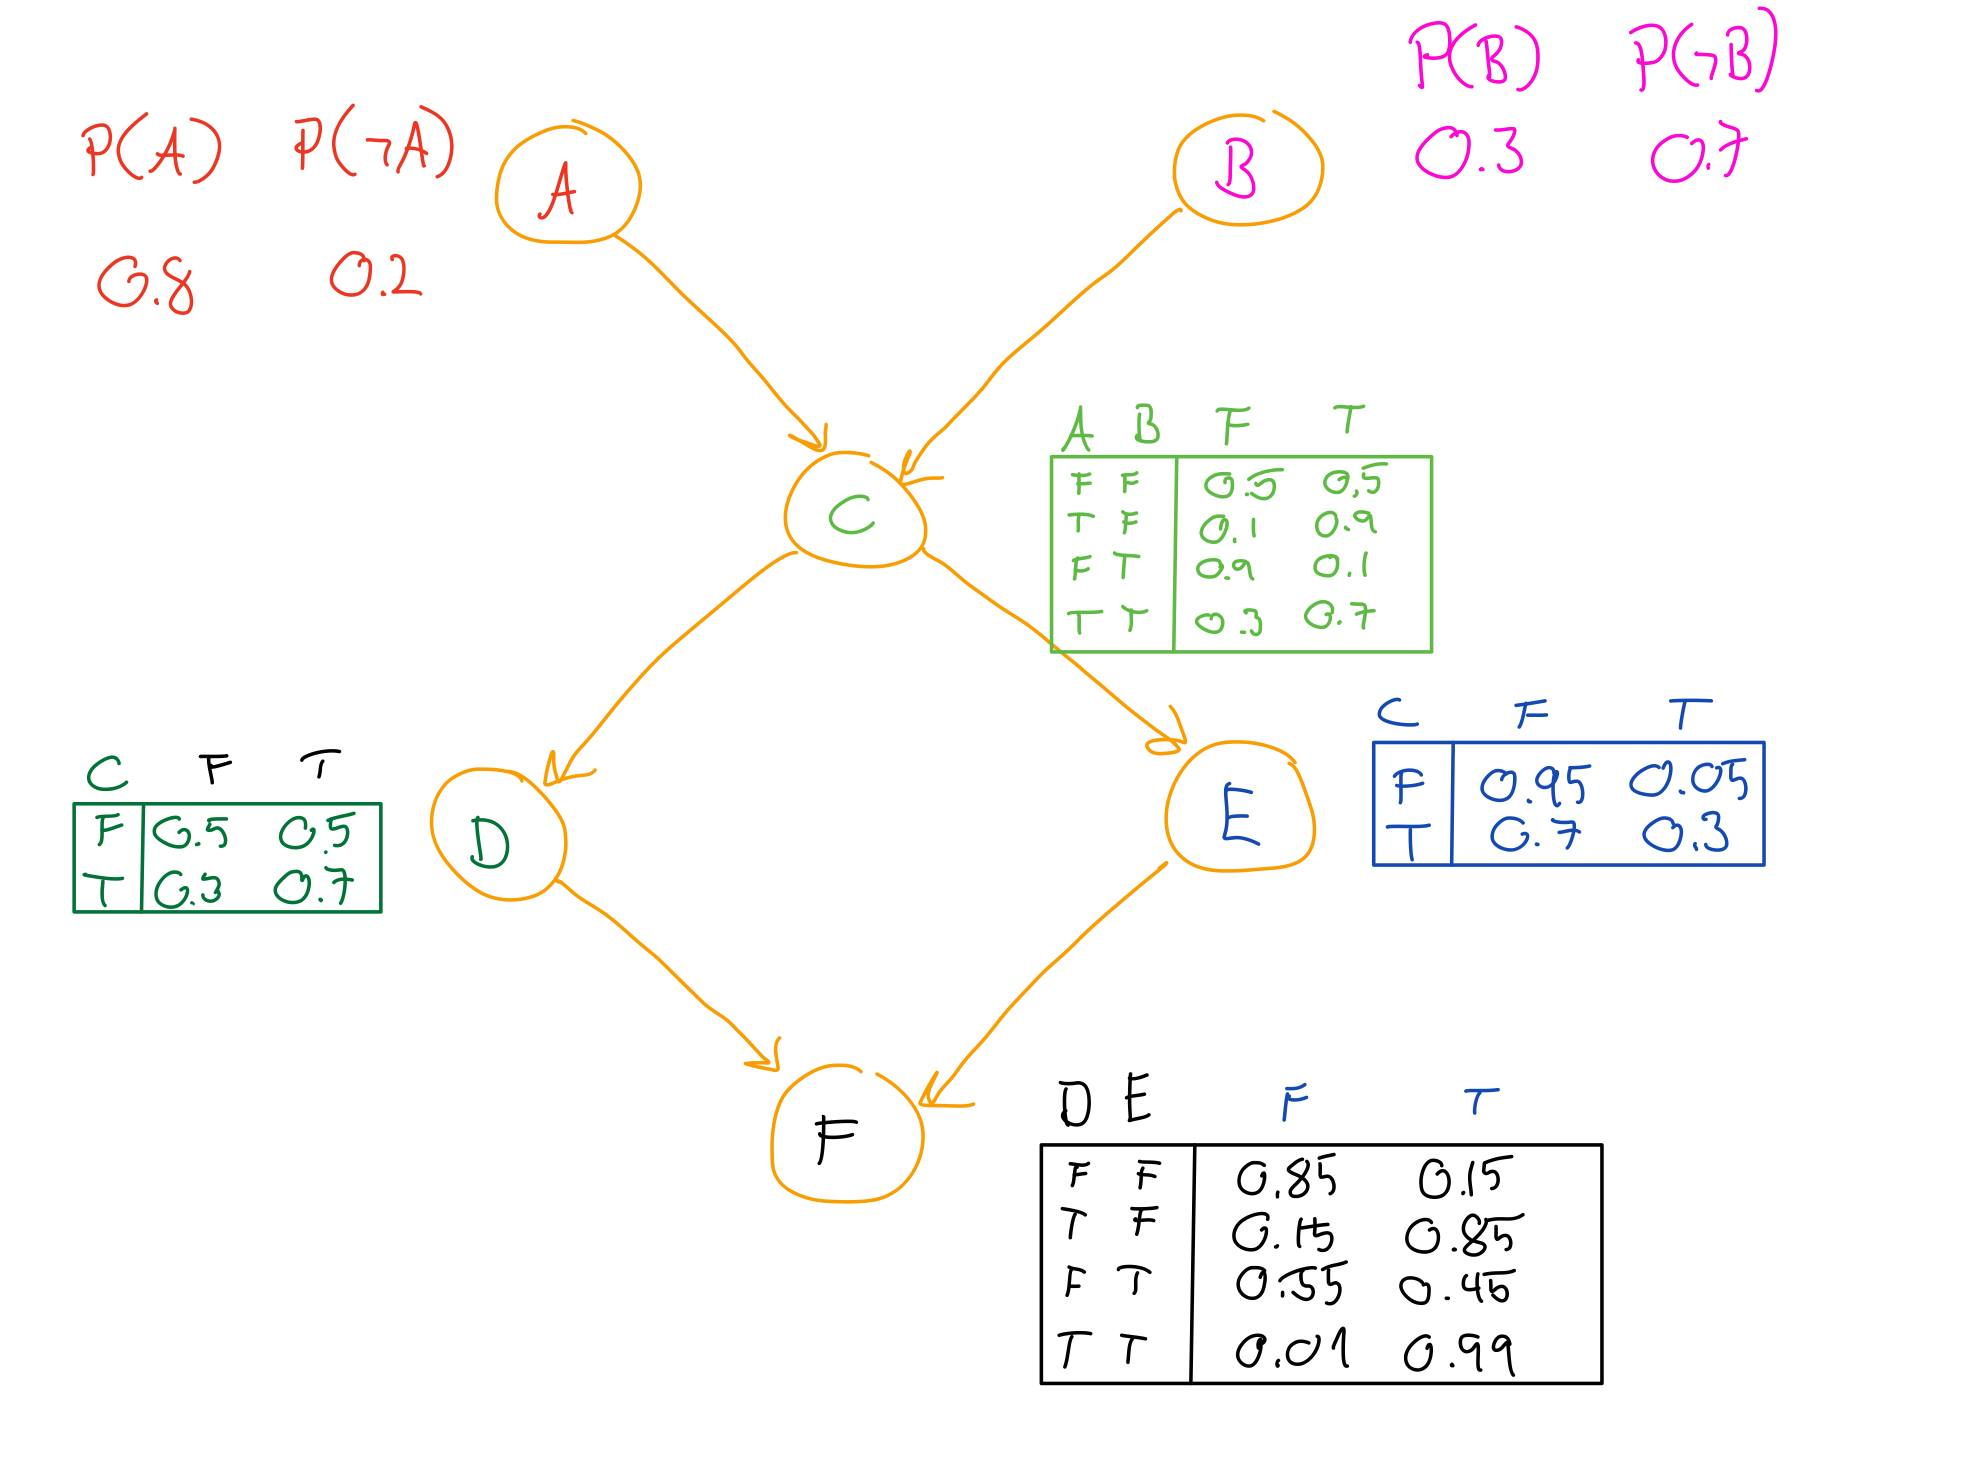

A = "My alarm does not go off in the morning"

B = "I am hungover"

C = "I go to school"

D = "I finish my CA today"

E = "I meet Helwig (In an elevator for instance)"

F = "I get an A in INF250"

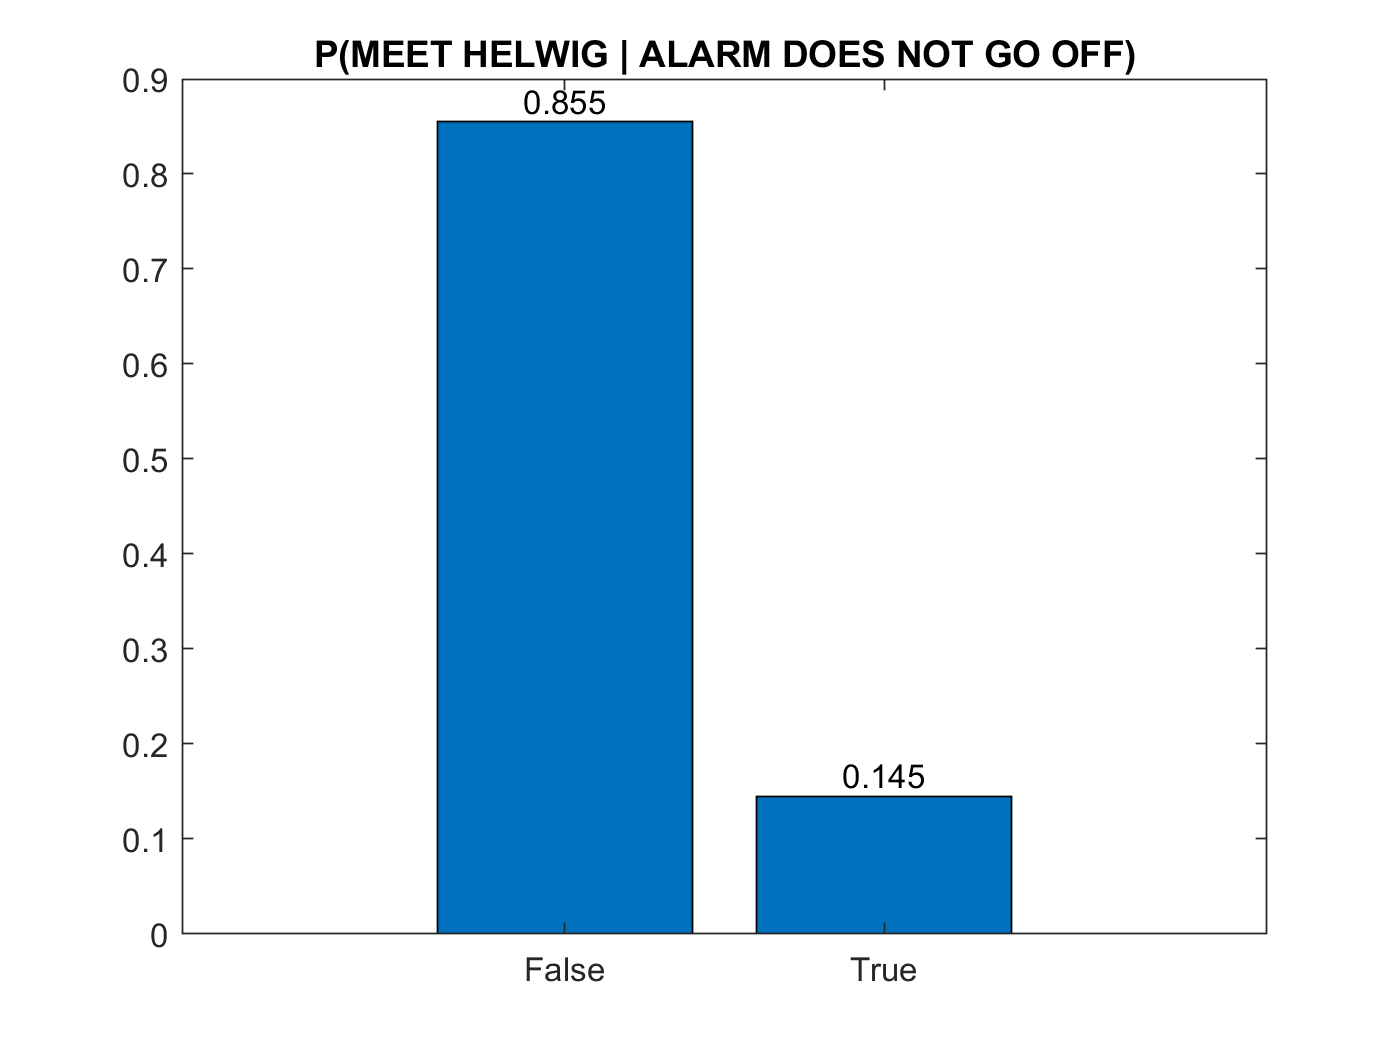


N = 6; 
dag = false(N,N);
A = 1; B = 2; C = 3; D = 4; E = 5; F = 6;
dag([A,B], C) = true;
dag(C, [D,E]) = true;
dag([D,E], F) = true;


node_sizes = 2*ones(1,N); 
my_bnet = mk_bnet(dag, node_sizes, 'names', {'ALARM','HUNGOVER','GET2SCHOOL','FINISH CA','MEET HELWIG','GET A'}, 'discrete', 1:6);
my_bnet.CPD{A} = tabular_CPD(my_bnet, A, [0.2, 0.8]);
my_bnet.CPD{B} = tabular_CPD(my_bnet, B, [0.7, 0.3]);
my_bnet.CPD{C} = tabular_CPD(my_bnet, C, [0.5, 0.1, 0.9, 0.3, 0.5, 0.9, 0.1, 0.7]);
my_bnet.CPD{D} = tabular_CPD(my_bnet, D, [0.5, 0.3, 0.5, 0.7]);
my_bnet.CPD{E} = tabular_CPD(my_bnet, E, [0.95, 0.7, 0.05, 0.3]);
my_bnet.CPD{F} = tabular_CPD(my_bnet, F, [0.85, 0.15, 0.55, 0.01, 0.15, 0.85, 0.45, 0.99]);


engine = jtree_inf_engine(my_bnet);
evidence = cell(1,N);

evidence{A} = 1;
[engine, loglik] = enter_evidence(engine, evidence);
marg = marginal_nodes(engine, E);
bar(marg.T);
text(1:2,marg.T,num2str(marg.T),'vert','bottom','horiz','center'); 
title("P(MEET HELWIG | ALARM DOES NOT GO OFF)")
set(gca,'xticklabel',{'False','True'})

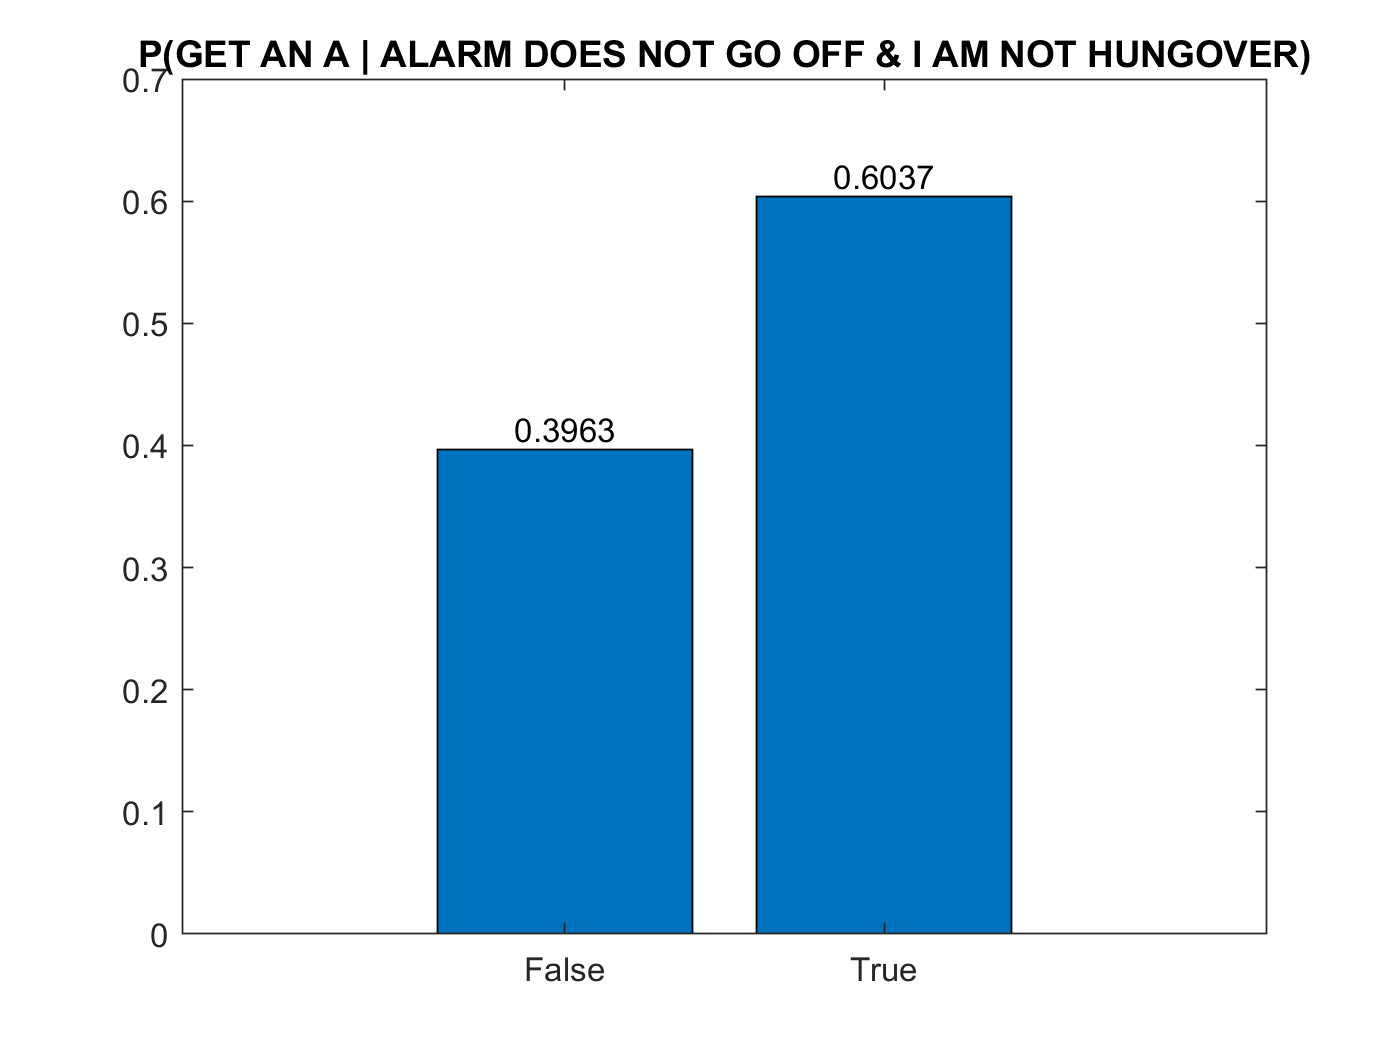




evidence{B} = 1;
[engine, loglik] = enter_evidence(engine, evidence);
marg = marginal_nodes(engine, F);
bar(marg.T)
text(1:2,marg.T,num2str(marg.T),'vert','bottom','horiz','center'); 
title("P(GET AN A | ALARM DOES NOT GO OFF & I AM NOT HUNGOVER)")
set(gca,'xticklabel',{'False','True'})

## Summary - mandatory to receive points:

Use the box below to tell us what you learned during this programming assignment for Bayesian networks. What were the interesting questions you tried to answer? What insights did you gain? What insight could others gain that use this network in future? Where would your Bayesian network be used: at university, at work, in the hospital, ... or somewhere completely different?

%{ --> add your answer as comment here!
% I chose to go with a more entertaining than realistic bayesian network to
% showcase its strengths. I created six nodes A-F, all leading to whether
% or not i get an A in the course INF250. 
% The first question i tried to answer is: "What is the probability of me
% meeting Helwig today, if my morning alarm does not go
% off?". Which appears to have a probability of 14.5%. 
% My second question is: "What is the probability of me getting an A in
% INF250, given that my alarm does not go off and i am not hungover?".
% Which seems to be around 60%. 

% This assigment really showcased how powerful bayesian networks can be.
% This is only scimming the very surface and yet, a model such as this can
% describe likelihoods given observed circumstances. 

% My network might not be applicable for very many others. But if i had to
% say someone, i would say future students of INF250 could gain from this
% network. (Particularly doing CAs and gaining insight from Helwig are the
% key factors to getting a good grade). This network would be used at the
% university. But it could surely be modified to be used at work (Hospital
% might be unlikely though). 

% A quick conclusion: I sense there are many similarities between decision
% trees and bayesian networks. Both can be used to make predictions, given
% observations. Very interesting!

%}